%% Clear temporary variables
clear variables

# **2D Example - X-ray absorption measurements of a soil column**

**Description:** This script loads and processes the X-ray dataset, which exhibits strong rank asymmetry. Various statistical analyses are performed, including the calculation of directional asymmetry, rank asymmetry, and variograms. The results are visualized using plots to interpret the directional properties and spatial characteristics of the dataset.

**Set Up Simulation Parameters**

This section outlines the parameters used for simulating the random fields and performing the computations. Note that we only keep x-section 5 to 53 as there are some artefacts on the others

list = 5:53; %% We only use x-sections 5 to 53 as there are some artefacts on the others.
nz = length(list);
% Load the data
for i = list
    if i<10
        X =  importfile(['E5 - XRays/X-ray-tomography/rastert_juap0',  num2str(i) ,'.txt']);
    else
        X =  importfile(['E5 - XRays/X-ray-tomography/rastert_juap',  num2str(i) ,'.txt']);
    end
    X(X==1) = nan;
    [nx, ny] = size(X);
    X = reshape(X(:,:,1),[nx*ny 1]);
    
    Z(:,i-min(list)+1) = X;
end

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

Z=ECDF(Z);
X=ECDF(X);
x0 = grille3(1,nx,1,1,ny,1,1,nz,1);
Z = reshape(Z,[], 1);
V = reshape(Z,[], 1);

## Display the dataset

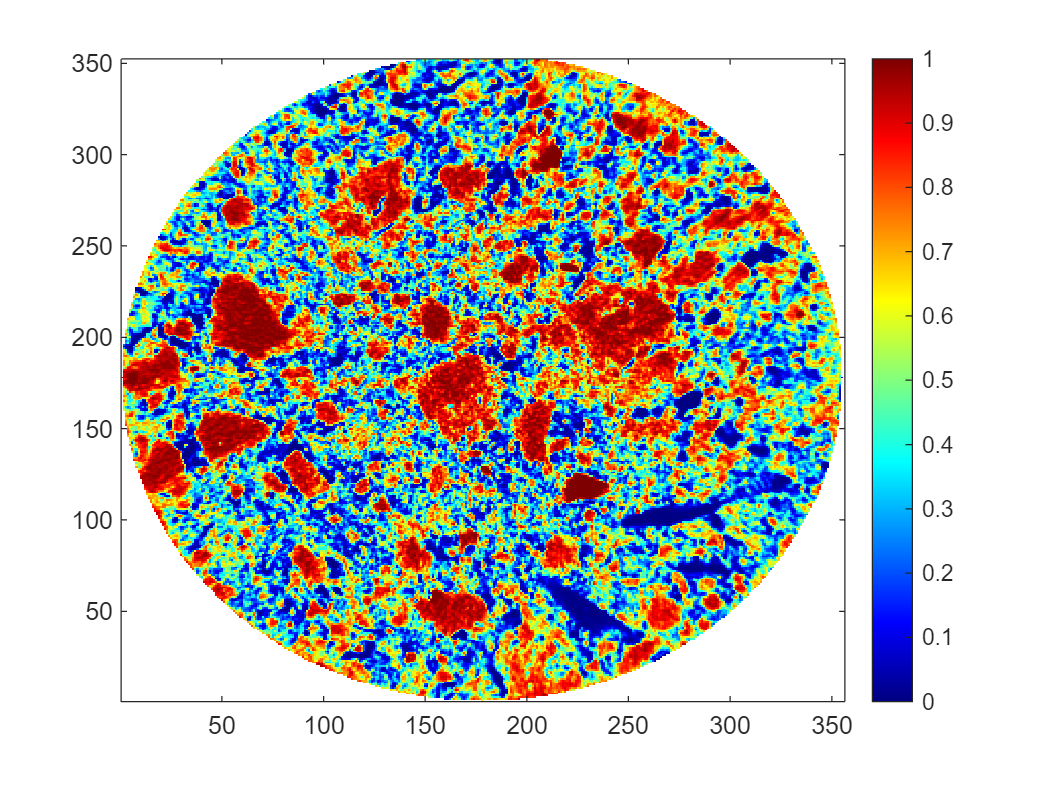

figure(1)
imagesc(reshape(X,[nx ny]),'AlphaData',~isnan(reshape(X,[nx ny])));
colorbar();
clim([0 1])
set(gca,'YDir','normal')
colormap('jet')

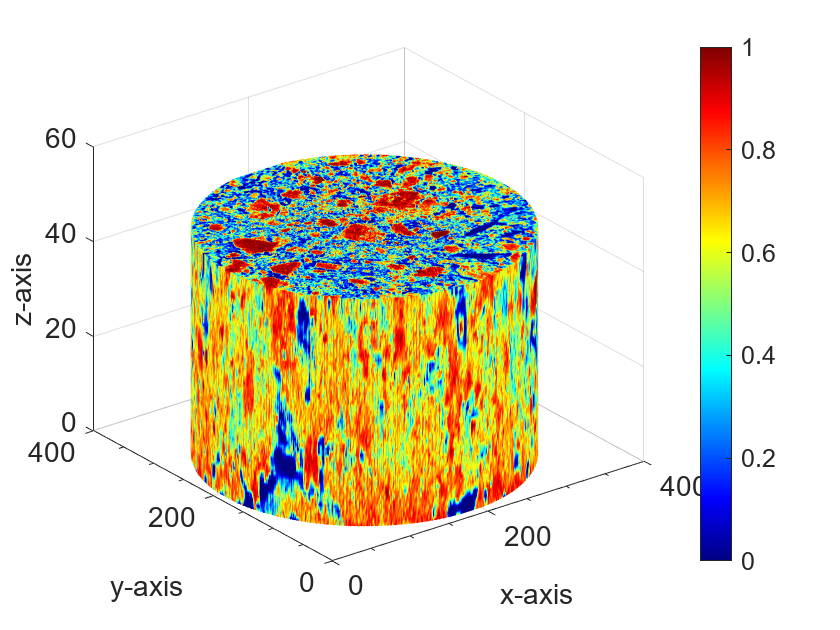


figure(2)
% Define the slices you want to visualize
x_slice = 1: size(reshape(V,nx,ny,nz), 2) ; % Slice in the middle of the x-dimension
y_slice = 1: size(reshape(V,nx,ny,nz), 1) ; % Slice in the middle of the y-dimension
z_slice = 1: size(reshape(V,nx,ny,nz), 3) ; % Slice in the middle of the z-dimension
slice(reshape(V,nx,ny,nz), x_slice, y_slice, z_slice);
colorbar()
shading interp;
xlabel('x-axis')
ylabel('y-axis')
zlabel('z-axis')
fontsize(gca, 14, 'points')
set(gca,'XMinorTick','on')
set(gca,'YMinorTick','on')
colormap('jet')


figure(3)
imagesc3D(reshape(V,nx,ny,nz));
colormap('hot')

**Compute the directional asymmetry**

This section calculates the directional asymmetry of the chloride concentration dataset. The data is classified as non-categorical by setting `categ = 0`, and visualization is disabled with `display = 0`. The field is transformed into rank values by specifying `rank = 1`, while the operation for calculating directional asymmetry is defined with `icode = 8`.

Next, 100 Gaussian random fields (GRFs) with the same variogram as the dataset are simulated using the `fftma` function. For each realization, the directional asymmetry is calculated with `GeoStatFFT`, and the results are stored in `gh1`.

The results are visualized in Figure 42, where the asymmetry values for each GRF realization are shown as light gray lines. The mean asymmetry is represented by a bold black line, with dashed lines marking the 5th and 95th percentiles. We used `GeoStatFFT_ndir` to compute the experimental directional asymmetry in multiple directions: azimuths of 0°, 22.5°, 45°, 67.5°, 90°, 112.5°, 135°, and 157.5°, with an angular tolerance of 10°. A maximum distance of 40 pixels with 10 equidistant classes was used. The `GeoStatFFT_ndir` results are plotted as red dots.

The plot includes labels for the x-axis ("Distance") and y-axis ("Directional Asymmetry Value"), as well as a legend. Axis limits and minor ticks have been adjusted for improved readability

categ = 0;
display = 1;
icode = 8;
rank = 1 ;

[gh, nh]=GeoStatFFT(x0,Z,icode,categ,display,1);
% Simulation of random fields
[z]=fftma([2 6 6 0],1,45124241,100,nx,1,ny,1);
display = 0 ;
for i =1:100
    gh1{i} = GeoStatFFT(grille2(1,nx,1,1,ny,1),z(:,i),icode,categ,display,rank);
end

figure(8)
for i=1:100
    plot(0:length(gh1{i}{1,1}(nx:end,ny))-1, gh1{i}{1,1}(nx:end,ny),'color', [0.9 0.9 0.9], LineWidth=1)
    hold on
    gmean(:,i) = gh1{i}{1,1}(nx:end,ny);
end
plot(0:length(mean(gmean,2))-1,mean(gmean,2), '-k',LineWidth=1.5)
hold on
plot(0:length(quantile(gmean,0.05,2))-1,quantile(gmean,0.05,2),'--k',LineWidth=1)
hold on
plot(0:length(quantile(gmean,0.95,2))-1,quantile(gmean,0.95,2),'--k',LineWidth=1)
hold on
h1 = plot(0:length(gh{1,1}(nx:end,ny,nz))-1,gh{1,1}(nx:end,ny,nz),'-g',LineWidth=2);
hold on
h2 = plot(0:length(gh{1,1}(nx,ny:end,nz))-1,gh{1,1}(nx,ny:end,nz),'-r',LineWidth=2);
hold on
h3 = plot(0:length(gh{1,1}(nx,ny,nz:round(3*nz/2)))-1,reshape(gh{1,1}(nx,ny,nz:round(3*nz/2)),1,[]),'-b',LineWidth=2);
legend([h1 h2 h3],{'x-axis', 'y-axis', 'z-axis'})
xlabel('Distance')
ylabel('Directional asymmetry value')
fontsize(gca, 14, 'points')
xlim([0 floor(nx/8)])
ylim([-0.02 0.02])
set(gca,'XMinorTick','on')
set(gca,'YMinorTick','on')

**Compute the bivariate (or rank) asymmetry**

We generate the same graph but set `icode = 7` to calculate rank asymmetry.

%% Compute Rank Asymmetry
categ = 0;
display = 1;
icode = 9;
rank = 1 ;

[gh, nh]=GeoStatFFT(x0,Z,icode,categ,display,1);
% Simulation of random fields
[z]=fftma([2 6 6 0],1,45124241,100,nx,1,ny,1);
display = 0 ;
for i =1:100
    gh1{i} = GeoStatFFT(grille2(1,nx,1,1,ny,1),z(:,i),icode,categ,display,rank);
end

figure(32)
for i=1:100
    plot(0:length(gh1{i}{1,1}(nx:end,ny))-1, gh1{i}{1,1}(nx:end,ny),'color', [0.9 0.9 0.9], LineWidth=1)
    hold on
    gmean(:,i) = gh1{i}{1,1}(nx:end,ny);
end
plot(0:length(mean(gmean,2))-1,mean(gmean,2), '-k',LineWidth=1.5)
hold on
plot(0:length(quantile(gmean,0.05,2))-1,quantile(gmean,0.05,2),'--k',LineWidth=1)
hold on
plot(0:length(quantile(gmean,0.95,2))-1,quantile(gmean,0.95,2),'--k',LineWidth=1)
hold on
h1 = plot(0:length(gh{1,1}(nx:end,ny,nz))-1,gh{1,1}(nx:end,ny,nz),'-g',LineWidth=2);
hold on
h2 = plot(0:length(gh{1,1}(nx,ny:end,nz))-1,gh{1,1}(nx,ny:end,nz),'-r',LineWidth=2);
hold on
h3 = plot(0:length(gh{1,1}(nx,ny,nz:round(3*nz/2)))-1,reshape(gh{1,1}(nx,ny,nz:round(3*nz/2)),1,[]),'-b',LineWidth=2);
legend([h1 h2 h3],{'x-axis', 'y-axis', 'z-axis'})
xlabel('Distance')
ylabel('Rank asymmetry value')
fontsize(gca, 14, 'points')
xlim([0 floor(nx/8)])
ylim([-0.02 0.03])
set(gca,'XMinorTick','on')
set(gca,'YMinorTick','on')

**Compute rank correlation**

We generate the same graph but set `icode = 10` to calculate rank correlation.

categ = 0;
display = 1;
icode = 10;
rank = 1 ;

[gh, nh]=GeoStatFFT(x0,Z,icode,categ,display,1);

% Simulation of random fields
[z]=fftma([2 6 6 0],1,45124241,100,nx,1,ny,1);
display = 0 ;
for i =1:100
    gh1{i} = GeoStatFFT(grille2(1,nx,1,1,ny,1),z(:,i),icode,categ,display,rank);
end

figure(52)
for i=1:100
    plot(0:length(gh1{i}{1,1}(nx:end,ny))-1, gh1{i}{1,1}(nx:end,ny),'color', [0.9 0.9 0.9], LineWidth=1)
    hold on
    gmean(:,i) = gh1{i}{1,1}(nx:end,ny);
end
plot(0:length(mean(gmean,2))-1,mean(gmean,2), '-k',LineWidth=1.5)
hold on
plot(0:length(quantile(gmean,0.05,2))-1,quantile(gmean,0.05,2),'--k',LineWidth=1)
hold on
plot(0:length(quantile(gmean,0.95,2))-1,quantile(gmean,0.95,2),'--k',LineWidth=1)
hold on
h1 = plot(0:length(gh{1,1}(nx:end,ny,nz))-1,gh{1,1}(nx:end,ny,nz),'-g',LineWidth=2);
hold on
h2 = plot(0:length(gh{1,1}(nx,ny:end,nz))-1,gh{1,1}(nx,ny:end,nz),'-r',LineWidth=2);
hold on
h3 = plot(0:length(gh{1,1}(nx,ny,nz:round(3*nz/2)))-1,reshape(gh{1,1}(nx,ny,nz:round(3*nz/2)),1,[]),'-b',LineWidth=2);
legend([h1 h2 h3],{'x-axis', 'y-axis', 'z-axis'})
xlabel('Distance')
ylabel('Rank correlation value')
fontsize(gca, 14, 'points')
xlim([0 floor(nx/8)])
ylim([-0.2 1.1])
set(gca,'XMinorTick','on')
set(gca,'YMinorTick','on')

**Compute Variogram**

We generate the same graph but set `icode = 1` to calculate variogram.

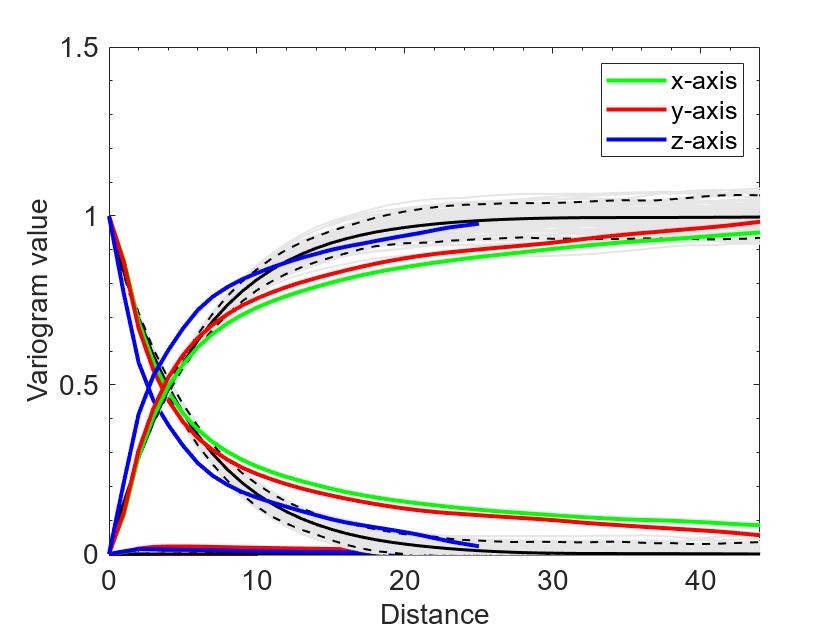

categ = 0;
display = 1;
icode = 1;
rank = 1 ;
Z(Z==0)=0.0000001;
Z(Z==1)=0.9999999;
[gh, nh]=GeoStatFFT(x0,norminv(Z),icode,categ,display,1);

% Simulation of random fields
[z]=fftma([2 6 6 0],1,45124241,100,nx,1,ny,1);
display = 0 ;
for i =1:100
    gh1{i} = GeoStatFFT(grille2(1,nx,1,1,ny,1),z(:,i),icode,categ,display,rank);
end

figure(100)
for i=1:100
    plot(0:length(gh1{i}{1,1}(nx:end,ny))-1, gh1{i}{1,1}(nx:end,ny),'color', [0.9 0.9 0.9], LineWidth=1)
    hold on
    gmean(:,i) = gh1{i}{1,1}(nx:end,ny);
end
plot(0:length(mean(gmean,2))-1,mean(gmean,2), '-k',LineWidth=1.5)
hold on
plot(0:length(quantile(gmean,0.05,2))-1,quantile(gmean,0.05,2),'--k',LineWidth=1)
hold on
plot(0:length(quantile(gmean,0.95,2))-1,quantile(gmean,0.95,2),'--k',LineWidth=1)
hold on
h1 = plot(0:length(gh{1,1}(nx:end,ny,nz))-1,gh{1,1}(nx:end,ny,nz),'-g',LineWidth=2);
hold on
h2 = plot(0:length(gh{1,1}(nx,ny:end,nz))-1,gh{1,1}(nx,ny:end,nz),'-r',LineWidth=2);
hold on
h3 = plot(0:length(gh{1,1}(nx,ny,nz:round(3*nz/2)))-1,reshape(gh{1,1}(nx,ny,nz:round(3*nz/2)),1,[]),'-b',LineWidth=2);
legend([h1 h2 h3],{'x-axis', 'y-axis', 'z-axis'})
xlabel('Distance')
ylabel('Variogram value')
fontsize(gca, 14, 'points')
xlim([0 floor(nx/8)])
ylim([0 1.5])
set(gca,'XMinorTick','on')
set(gca,'YMinorTick','on')

**Compute Experimental Rank Asymmetry**

Reload the data, as it is not compatible with the previous figure. We sample 100, 500, 2,000, and 5,000 data points from the dataset to investigate the effect of the sample size on the experimental rank asymmetry value.

clear variables
%% Reload data
list = 5:53; %% We only use x-sections 5 to 53 as there are some artefacts on the others.
nz = length(list);
% Load the data
for i = list
    i
    if i<10
        X =  importfile(['E5 - XRays/X-ray-tomography/rastert_juap0',  num2str(i) ,'.txt']);
    else
        X =  importfile(['E5 - XRays/X-ray-tomography/rastert_juap',  num2str(i) ,'.txt']);
    end
    X(X==1) = nan;
    [nx, ny] = size(X);
    X = reshape(X(:,:,1),[nx*ny 1]);
    
    Z(:,i-min(list)+1) = X;
end

i = 5

Unable to perform assignment because the size of the left side is 6140288-by-1 and the size of the right side is 125312-by-1.

Z=ECDF(Z);
X=ECDF(X);
x0 = grille3(1,nx,1,1,ny,1,1,nz,1);
Z = reshape(Z,[], 1);
V = reshape(Z,[], 1);

%% Analysis
list = [100, 500, 2000, 5000];
for iii = 1:4
    nbdata = list(iii);

    x0 = grille2(1,nx,1,1,ny,1);
    ZZ = reshape(Z,[nx ny nz]);
    ZZ = reshape(ZZ(:,:,28),[],1);
    p = haltonset(2);
    id_x = floor(p(100+(nbdata*i +1):100+(nbdata*i +1)+nbdata-1,1)*nx)+1;
    id_y = floor(p(100+(nbdata*i +1):100+(nbdata*i +1)+nbdata-1,2)*nx)+1;
    id = sortrows([id_x id_y ],[1 2]);
    [ind{i}, I] = unique((id(:,1)-1)*(nx) + id(:,2));
    ind_all = (1:nx*ny)';
    ZZ(~ismember(ind_all,ind{i}),:)=nan;

    categ = 0;
    display = 0;
    icode = 9;
    rank = 1 ;

    [gh, nh]=GeoStatFFT(x0,ZZ,icode,categ,display,rank);

    nbdist= 10;
    ang=[0,1,2,3,4,5,6,7]'*22.5;
    tol_ang = 15;
    max_dist = 40;
    dist = [(0:nbdist-1);(1:nbdist)]'*(max_dist/nbdist);
    [gh_dir, nh_dir, lag_dir] = GeoStatFFT_ndir(gh, nh,dist, ang, tol_ang);

    % Simulation of random fields
    [z]=fftma([2 6 6 0 ],1,45124241,100,nx,1,ny,1);
    display = 0 ;
    for i =1:100
        [gh1{i}, nh1{i}] = GeoStatFFT(x0,z(:,i),icode,categ,display,rank);
        [gh1_dir{i}, nh1_dir{i}, lag1_dir{i}] = GeoStatFFT_ndir(gh1{i}, nh1{i}, dist, ang, tol_ang);
    end

    figure(51+iii)
    ii=1; j=1;
    for k = 1: length(ang)
        subplot(3, 3, k)
        hold on
        for i=1:100
            plot(lag1_dir{i}{ii,j}(:,k), gh1_dir{i}{ii,j}(:,k),'color', [0.9 0.9 0.9], LineWidth=1)
            hold on
            gmean(:,i) = gh1_dir{i}{ii,j}(:,k);
        end
        plot(lag1_dir{i}{ii,j}(:,k),mean(gmean,2), '-k',LineWidth=1.5)
        hold on
        plot(lag1_dir{i}{ii,j}(:,k),quantile(gmean,0.05,2),'--k',LineWidth=1)
        hold on
        plot(lag1_dir{i}{ii,j}(:,k),quantile(gmean,0.95,2),'--k',LineWidth=1)
        hold on

        plot(lag_dir{ii,j}(:,k), gh_dir{ii,j}(:,k), 'sr',MarkerEdgeColor='red',MarkerFaceColor='red',MarkerSize=4)
        %t = text(lag_dir{ii,j}(:,k) + 0.005, gh_dir{ii,j}(:,k) + 0.005, string(nh_dir{ii,j}(:,k)));
        % Adjust font size for each text element
        %for kk = 1:length(t)
        %    t(kk).FontSize = 6;
        %end

        xlim([0, 40]);
        ylim([-0.07, 0.07]);
        fontsize(gca, 8, 'points')
        set(gca,'XMinorTick','on')
        set(gca,'YMinorTick','on')
        title(['Dir. ', num2str(ang(k))],'FontSize',10);
        xlabel('Distance','FontSize',8)
        ylabel('Rank asym. value','FontSize',8)
    end
    % Save the figure as an EPS file with consistent font sizes
    if iii==1
        print('E5 - XRays/RankAssExp_100', '-depsc'); % Replace 'your_figure_name' with your desired filename
    elseif iii==2
        print('E5 - XRays/RankAssExp_500', '-depsc'); % Replace 'your_figure_name' with your desired filename
    elseif iii==3
        print('E5 - XRays/RankAssExp_2000', '-depsc'); % Replace 'your_figure_name' with your desired filename
    elseif iii==4
        print('E5 - XRays/RankAssExp_5000', '-depsc'); % Replace 'your_figure_name' with your desired filename
    end
end